% Define initial conditions
x0 = 0; % Initial x position
y0 = 0; % Initial y position
z0 = 0; % Initial z position
vx0 = 0; % Initial x velocity
vy0 = 0; % Initial y velocity
vz0 = 0; % Initial z velocity

% Define time range for simulation
t0 = 0; % Start time
tf = 10; % End time
dt = 1; % Time step
t = t0:dt:tf; % Time range for simulation

% Solve differential equations using ode45
y_0 = [x0, y0, z0, vx0, vy0, vz0]; % Initial conditions
[t, y] = ode45(@rocketDynamics, t, y_0);

% Plot results
comet3(y(:,1), y(:,2), y(:,3)); % Position in 3D space
xlabel('x');
ylabel('y');
zlabel('z');

% Plot all results with animation 
clf
plotMD(y,t); 

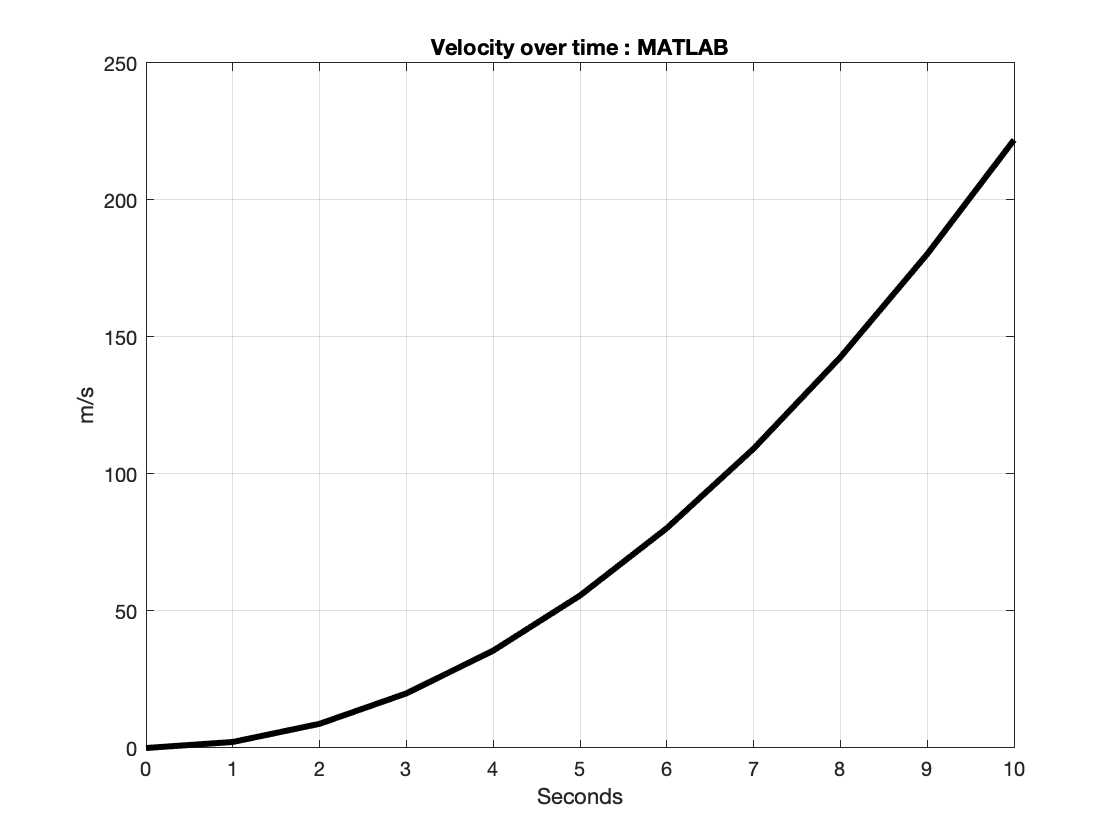

% Plots for the report - Matlab 

% Hastighet
plot(t, y(:,3),'black','LineWidth',3); 
title("Velocity over time : MATLAB")
xlabel("Seconds")
ylabel("m/s")
hold off 
grid on 

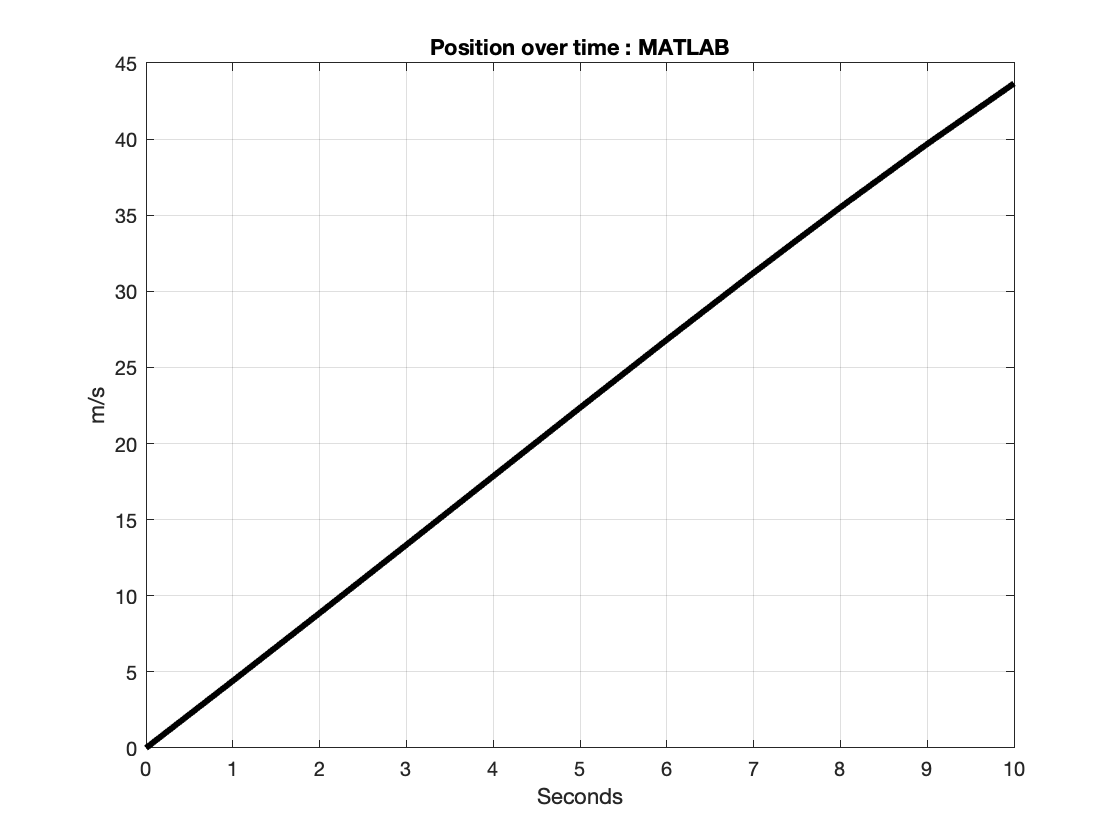


% Position
plot (t, y(:,6),'black','LineWidth',3);
title("Position over time : MATLAB")
xlabel("Seconds")
ylabel("m/s")
hold off
grid on 

% Plots for the report - JS 

% Hastighet 
Velocity = [1,2,3,4,5,6,7,8,9,10,11];
grid on
hold off

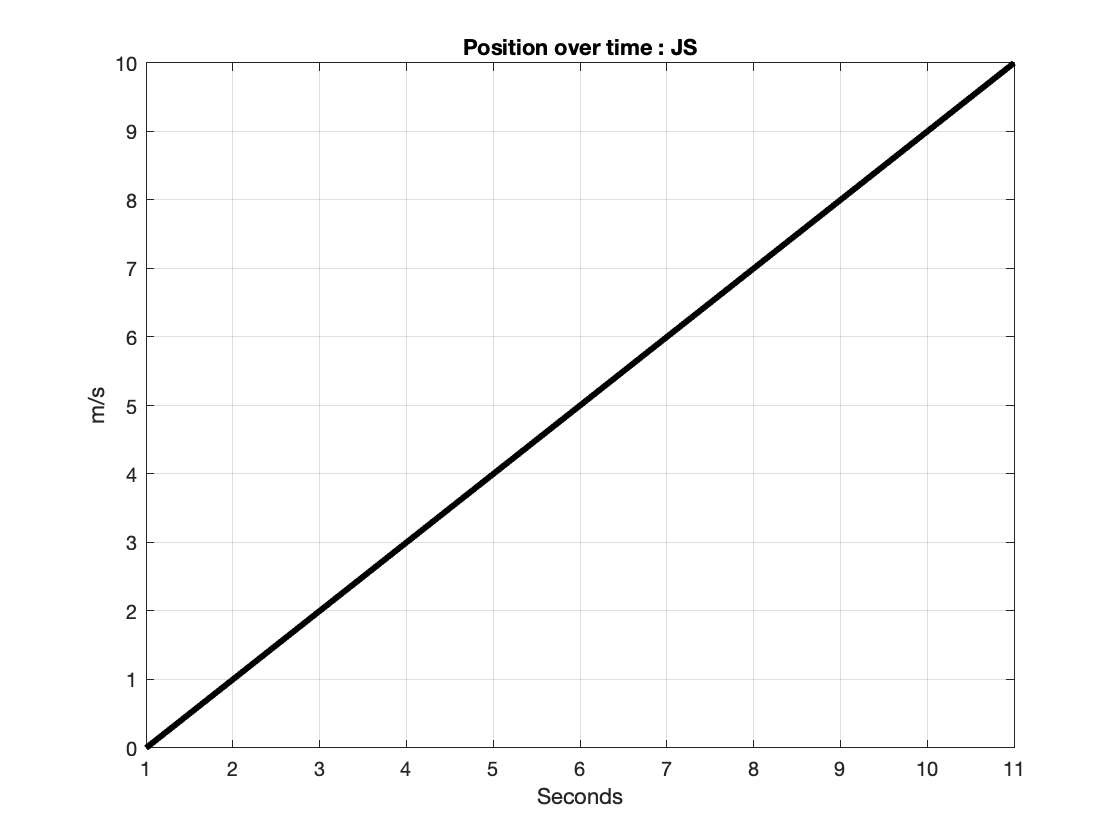

plot(Velocity,t,'black','LineWidth',3)
title("Position over time : JS")
xlabel("Seconds")
ylabel("m/s")

% Position 
Position = [1,2,3,4,5,6,7,8,9,10,11];
grid on

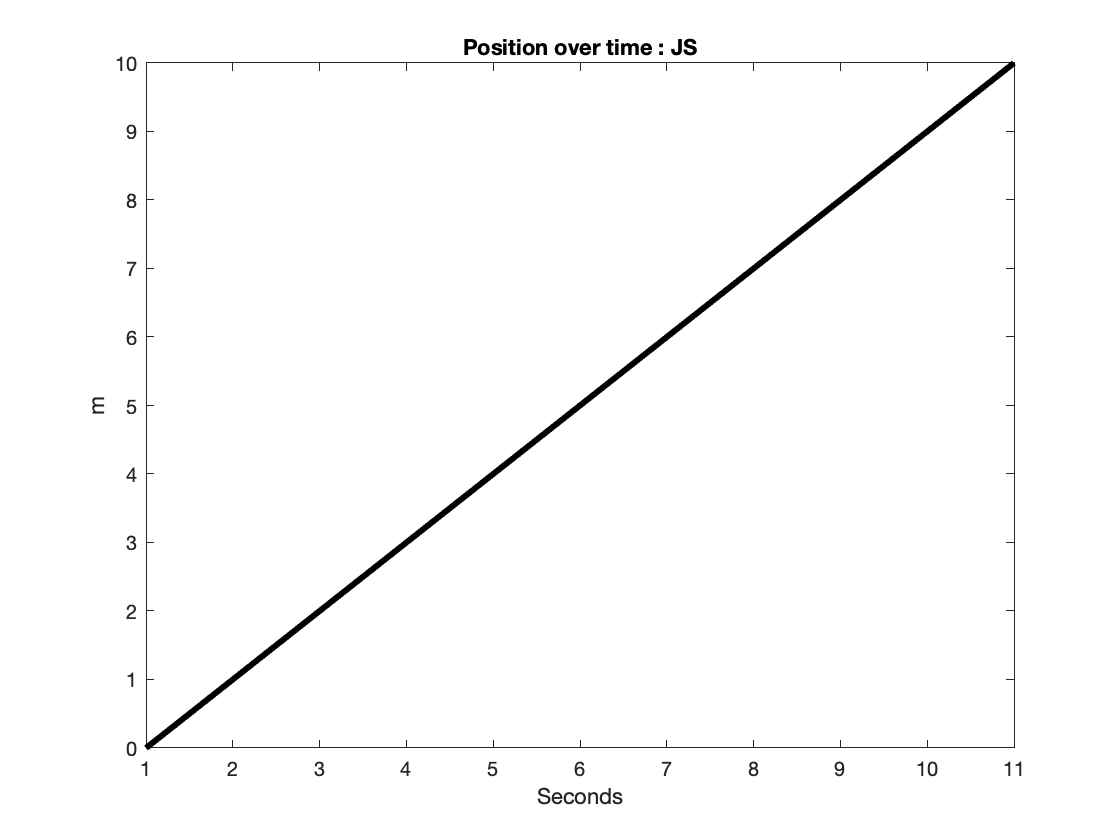

plot(Position,t,'black','LineWidth',3)
title("Position over time : JS")
xlabel("Seconds")
ylabel("m")